%{
Program to denoise images using low rank completion methods
Harsh Shah and Pranava Singhal 
%}
addpath '.\MMread';
rng(73);

[video, audio] = mmread('.\data\akiyo_cif.y4m');

% reading the meta data and frames of the video 
H = video.height;
W = video.width;
K = 50;
num_channels = 3;
frames = zeros(H, W, num_channels, K);
for i=1:1:K
    frames(:, :, :, i) = uint8(video.frames(i).cdata);
end
frames = uint8(frames);

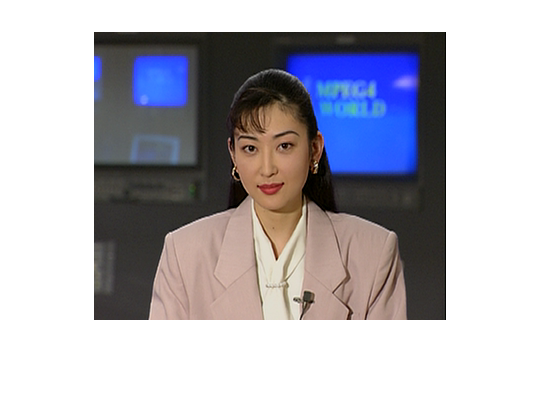

imshow(frames(:, :, :, 1))

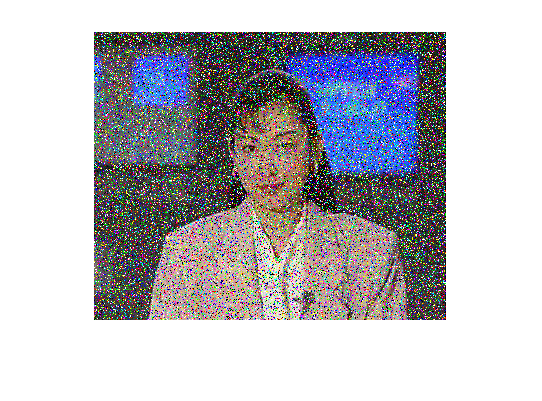

% noise generation
sigma = 20; 
kappa = 5;
mu = 0;
s = 0.3;
groundTruth = frames(:, :, :, 1);
imshow(noisify(groundTruth, sigma, mu, kappa, s));

noisy_video = zeros(H,W,num_channels,K);
for T = 1:K
    noisy_video(:,:,:,T) = noisify(frames(:,:,:,T), sigma, mu, kappa, s);
end

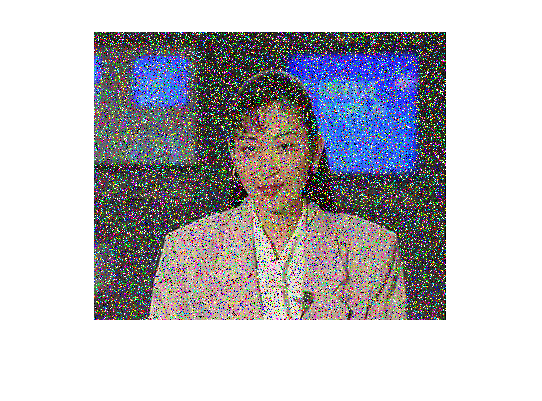

imshow(noisy_video(:,:,:,10))

% denoising using adaptive median filtering
[omega , denoised_frames] = ramf(noisy_video(:,:,:,1:2));

imshow(denoised_frames(:,:,:,1));

% soft_shrinkage testing
%soft_shrinkage(x, 2)

% nuclear norm testing
%nucnorm = norm(eig(x),1);

[matchingPatches, indices] = patchMatch(denoised_frames(101:108,101:108,1,1),denoised_frames(:,:,1,:),5);
[omega_1, Pjk] = concatMatching(1, 50, matchingPatches, indices, omega);

Pjk

Pjk =     0.4118    0.0854    0.3724    0.2454    0.3321    0.3689    0.3568    0.2832    0.4503    0.3053
    0.4118    0.2125    0.3780    0.1293    0.3307    0.1608    0.3129    0.3703    0.3750    0.3700
    0.2420    0.3200    0.2156    0.1870    0.3307    0.1569    0.2527    0.2378    0.3750    0.3053
    0.2676    0.3200    0.3716    0.2325    0.3903    0.1512    0.3053    0.2401    0.1458    0.3386
    0.3928    0.1415    0.3625    0.2681    0.3903    0.1833    0.3700    0.2393    0.4047    0.2527
    0.4939    0.2335    0.4922    0.2011    0.3724    0.2460    0.3053    0.1518    0.5157    0.3578
    0.4939    0.2995    0.3771    0.2572    0.3964    0.5101    0.3386    0.4150    0.3672    0.3386
    0.4178    0.3247    0.1757    0.2572    0.5176    0.6521    0.2527    0.0991    0.5751    0.3152
    0.3368    0.0854    0.3212    0.2454    0.2582    0.1693    0.3129    0.2832    0.3511    0.3852
    0.2635    0.2208    0.3724    0.1877    0.2582    0.1608    0.2210    0.2378    0

omega_1

omega_1 =      1     0     0     0     0     0     0     0     1     0
     0     0     1     0     1     1     1     0     0     1
     0     0     0     1     0     0     1     0     1     1
     0     1     1     1     1     1     0     0     0     1
     1     0     0     0     1     0     1     0     0     1
     1     0     0     0     0     1     1     0     0     1
     1     1     1     1     0     1     1     0     0     1
     0     0     0     1     1     1     1     0     0     1
     1     1     0     1     1     0     1     1     0     0
     1     0     1     1     0     1     1     1     0     1


function [omega_1, Pjk] = concatMatching(frame_index, K, matchingPatches, indices, omega_video)
    Kxmatches = size(matchingPatches, 1);
    matches = floor(Kxmatches/K);
    ref_patch = matchingPatches(matches*(frame_index-1)+1,:,:,:);
    ref_patch_index = indices(matches*(frame_index-1)+1,:);
    matchingPatches(matches*(frame_index-1)+1,:,:,:) = matchingPatches(1,:,:,:);
    indices(matches*(frame_index-1)+1,:) = indices(1,:);
    matchingPatches(1,:,:,:) = ref_patch;
    indices(1,:) = ref_patch_index;
    patch_size = size(ref_patch,2);
    omega_patches = zeros(size(matchingPatches));
    Pjk = zeros(patch_size*patch_size, Kxmatches);
    omega_1 = zeros(patch_size*patch_size, Kxmatches);
    for c = 1:Kxmatches
        idx_i = indices(c,1);
        idx_j = indices(c,2);
        idx_T = indices(c,3);
        omega_patches(c,:,:,:) = omega_video(idx_i:idx_i+patch_size-1,idx_j:idx_j+patch_size-1,1,idx_T);
        Pjk(:,c) = reshape(matchingPatches(c,:,:,1),[patch_size*patch_size,1]);
        omega_1(:,c)  = reshape(omega_patches(c,:,:,1),[patch_size*patch_size,1]);
    end
end

function [matchingPatches, indices] = patchMatch(ref_patch, frames, matches_per_frame)
    num_channels = size(frames, 3);
    K = size(frames, 4);
    patch_size = size(ref_patch, 1);
    matchingPatches = zeros(K*matches_per_frame, patch_size, patch_size, num_channels);
    indices = zeros(K*matches_per_frame, 3);
    for T = 1:K
        [matchingPatches((T-1)*matches_per_frame+1:T*matches_per_frame,:,:,:),indices((T-1)*matches_per_frame+1:T*matches_per_frame,1:2)] = patchMatchPerFrame(ref_patch, frames(:,:,:,T), matches_per_frame);
        indices((T-1)*matches_per_frame+1:T*matches_per_frame,3) = T;
    end
end
function [matchingPatches, indices] = patchMatchPerFrame(ref_patch,frame,num_matches)
    H = size(frame, 1);
    W = size(frame, 2);
    num_channels = size(frame, 3);
    patch_size = size(ref_patch,1);
    MAD_array = zeros(H-patch_size+1, W-patch_size+1);
    for i = 1:H-patch_size+1
        for j = 1:W-patch_size+1
            patch_ij = frame(i:i+patch_size-1,j:j+patch_size-1,:);
            if ((rem(i,2)==1)&&(rem(j,2)==1))
                pattern = 'a';
            elseif ((rem(i,2)==0)&&(rem(j,2)==1))
                pattern = 'b';
            elseif ((rem(i,2)==0)&&(rem(j,2)==0))
                pattern = 'c';
            elseif ((rem(i,2)==1)&&(rem(j,2)==0))
                pattern = 'd';
            end
            MAD_array(i,j) = MAD(ref_patch, patch_ij,pattern);
        end
    end
    [lx,~] = size(MAD_array);
    [~,minIndices] = mink(MAD_array(:), num_matches);
    indices = zeros(size(minIndices,1),2);
    matchingPatches = zeros(size(minIndices,1),patch_size, patch_size, num_channels);
    for c = 1:size(minIndices,1)
        idx = minIndices(c)-1;
        idx_j = floor(idx/lx);
        idx_i = idx - idx_j*lx;
        idx_i = idx_i + 1;
        idx_j = idx_j + 1;
        indices(c,:) = [idx_i,idx_j];
        matchingPatches(c,:,:,:) = frame(idx_i:idx_i+patch_size-1,idx_j:idx_j+patch_size-1,:);
    end    
end

function MeanAbsDiff = MAD(patch1, patch2, pattern)
    patch_size = size(patch1, 1);
    assert(size(patch2,1) == patch_size);
    MeanAbsDiff = 0;
    if pattern == 'a'
        patch1_extract = patch1(1:2:patch_size,1:2:patch_size,:);
        patch2_extract = patch2(1:2:patch_size,1:2:patch_size,:);
        size_a = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_a*size_a);
    elseif pattern == 'b'
        patch1_extract = patch1(1:2:patch_size,2:2:patch_size,:);
        patch2_extract = patch2(1:2:patch_size,2:2:patch_size,:);
        size_b = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_b*size_b);
    elseif pattern == 'c'
        patch1_extract = patch1(2:2:patch_size,1:2:patch_size,:);
        patch2_extract = patch2(2:2:patch_size,1:2:patch_size,:);
        size_c = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_c*size_c);
    elseif pattern == 'd'
        patch1_extract = patch1(2:2:patch_size,2:2:patch_size,:);
        patch2_extract = patch2(2:2:patch_size,2:2:patch_size,:);
        size_d = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_d*size_d);
    elseif pattern == 'all'
        MeanAbsDiff = sum(abs(patch1- patch2),'all');
        MeanAbsDiff = MeanAbsDiff/(patch_size*patch_size);
    end
end

function for adding noise to a given image

groundTruth: uint8 

function result = noisify(groundTruth, sigma, mu, kappa, s)
    H = size(groundTruth, 1);
    W = size(groundTruth, 2);
    num_channels = size(groundTruth, 3);
    gaussian_noise = normrnd(mu, sigma, H, W, num_channels);
    poisson_noise = poissrnd(kappa, H, W, num_channels);
    
    result = double(groundTruth) + gaussian_noise + poisson_noise;
    
    result(result > 255) = 255;
    result(result < 0) = 0;

    for i=1:H
        for j=1:W
            if rand() < s
                result(i, j, :) = noisy_pixel(num_channels);
            end
        end
    end
    result = result/255;
end

% functin for generating salt and pepper noise
function pixel = noisy_pixel(num_channels)
    pixel = zeros(1, 1, 3);
    for i=1:num_channels
        if rand() < 0.5
            pixel(1, 1, i) = 0;
        else
            pixel(1, 1, i) = 255;
        end
    end
end

% function for soft shrinkage 
function result = soft_shrinkage(A, tau)
    [U, S, V] = svd(A);
    S(S>0) = S(S>0)-tau;
    S(S<0) = 0;
    result = U*S*V';
end

function patches = generatePatches_nonoverlap(image, patch_r, patch_c) 
    rows = size(image, 1);
    columns = size(image, 2);
    wholeBlockRows = floor(rows / patch_r);
    wholeBlockCols = floor(columns / patch_c);
    trailing_rows = rows - wholeBlockRows * patch_r;
    trailing_cols = columns - wholeBlockCols * patch_c;
    image3d_cell = mat2cell( image, [ patch_r * ones(1, wholeBlockRows), trailing_rows], [patch_c * ones(1, wholeBlockCols), trailing_cols], size(image, 3) );
    if trailing_rows == 0 && trailing_cols == 0
      patches = cat( ndims(image)+1, image3d_cell{1:end-1,1:end-1} );
    else
      display("Image size and patch size not compatible");    
    end
end

% function to generate overlapping patches
function patches = generatePatches_overlapping(image, patch_dim, stride)
    height = size(image, 1);
    width = size(image, 2);
    T = size(image, 3);
    assert(rem(height-patch_dim, stride) == 0);
    assert(rem(width-patch_dim, stride) == 0);
    blocks_x = (width-patch_dim)/stride+1;
    blocks_y = (height-patch_dim)/stride+1;
    
    patches = zeros(patch_dim, patch_dim, T, blocks_x*blocks_y);

    for i=1:blocks_x
        for j=1:blocks_y
            patch = image((j-1)*stride+1 : patch_dim+(j-1)*stride,(i-1)*stride+1 : patch_dim+(i-1)*stride, :);
            patches(:, :, :, (i-1)*blocks_y+j) = patch;
        end
    end
end

% for stiching the non-overlapping patches
function result = imageReconstruction_non_overlapping(all_patches, x_patches, y_patches)
    all_patches_size = size(all_patches);
    num_patches = all_patches_size(1);
    patch_size = all_patches_size(2);
    T = all_patches_size(4);
    assert(num_patches*patch_size*patch_size*T == y_patches*patch_size*x_patches*patch_size*T);
    reconstruction = zeros(y_patches*patch_size, x_patches*patch_size, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*patch_size+1:j*patch_size, (i-1)*patch_size+1:i*patch_size, :) = all_patches((i-1)*y_patches + j, :, :, :);
        end
    end
    result = reconstruction;
end

% function to stitch image from overlapping patches
function result = imageReconstruction_overlapping(all_patches, x_patches, y_patches, stride)
    all_patches_size = size(all_patches);
    patch_dim = all_patches_size(2);
    T = all_patches_size(4);
    height = patch_dim + stride*(y_patches-1);
    width = patch_dim + stride*(x_patches-1);
    
    reconstruction = zeros(height, width, T);
    count_mat = zeros(height, width, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + squeeze(all_patches((i-1)*y_patches + j, :, :, :));
            count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + ones(patch_dim, patch_dim, T);
        end
    end
    result = reconstruction./count_mat;  
end

% function for fixed point iteration(algorithm for matrix completion)
function result = fixed_point_iteration()

end

% function to reduce noise for patch matching
function result = level1_noise_reduction(all_patches)
    
end


% function for getting matching patches using cosine similarity
function result = patchmatching_cos_similarity(all_patches, reference_patch)
    
end


% function for getting matching patches using -three-step hierarchical search
function result = patchmatching_three_step(all_patches, reference_patch)
       
end


function [omega, denoised_frames] = ramf(frames)
    H = size(frames, 1);
    W = size(frames, 2);
    num_channels = size(frames, 3);
    K = size(frames, 4);
    denoised_frames = double(zeros(size(frames)));
    omega = zeros(size(frames));
    for T = 1:K
        for i = 1:H
            for j = 1:W
                % stage 1 filtering
                for window_size = 3:2:floor(min(H/2,W/2))
                    delta = floor((window_size-1)/2);
                    pixels_in_window = zeros(window_size, window_size, num_channels);
                    for r = (i-delta):(i+delta)
                        for s = (j-delta):(j+delta)
                            if((r>= 1) && (s>=1) && (r<=H) && (s<= W))
                                pixels_in_window(r-i+delta+1,s-j+delta+1, :) = frames(r,s,:,T);
                            else
                                % locations outside frame
                                pixels_in_window(r-i+delta+1,s-j+delta+1, :) = -1;
                            end
                        end
                    end
                    
                    x_median = zeros([1,1,num_channels]);
                    x_min = zeros([1,1,num_channels]);
                    x_max = zeros([1,1,num_channels]);
                    
                    for channel = 1:num_channels
                        pixels_in_channel = pixels_in_window(:,:,channel);
                        valid_pixels = pixels_in_channel(pixels_in_channel >= 0);
                        x_median(:,:,channel) = median(valid_pixels(:));
                        x_min(:,:,channel) = min(valid_pixels(:));
                        x_max(:,:,channel) = max(valid_pixels(:));
                    end 
                    
                    T_minus = x_median - x_min;
                    T_plus = x_median - x_max;
                    if(sum(T_minus>0 & T_plus<0) == num_channels)
                        % stage 2 filtering
                        x_ij = frames(i,j,:,T);
                        %x_ij_squeeze = reshape(x_ij,[1,3]);
                                            
                        U_minus = x_ij - x_min;
                        U_plus = x_ij - x_max;

                        if(sum(U_minus>0 & U_plus<0) == num_channels)
                            denoised_frames(i,j,:,T) = x_ij;
                        else
                            denoised_frames(i,j,:,T) = x_median;
                            omega(i,j,:,T) = 1;
                        end
                        break;
                    end   
                end
    
            end
        end
    end  
end



